# Location Analysis

clear;
clc;

## Wild Type

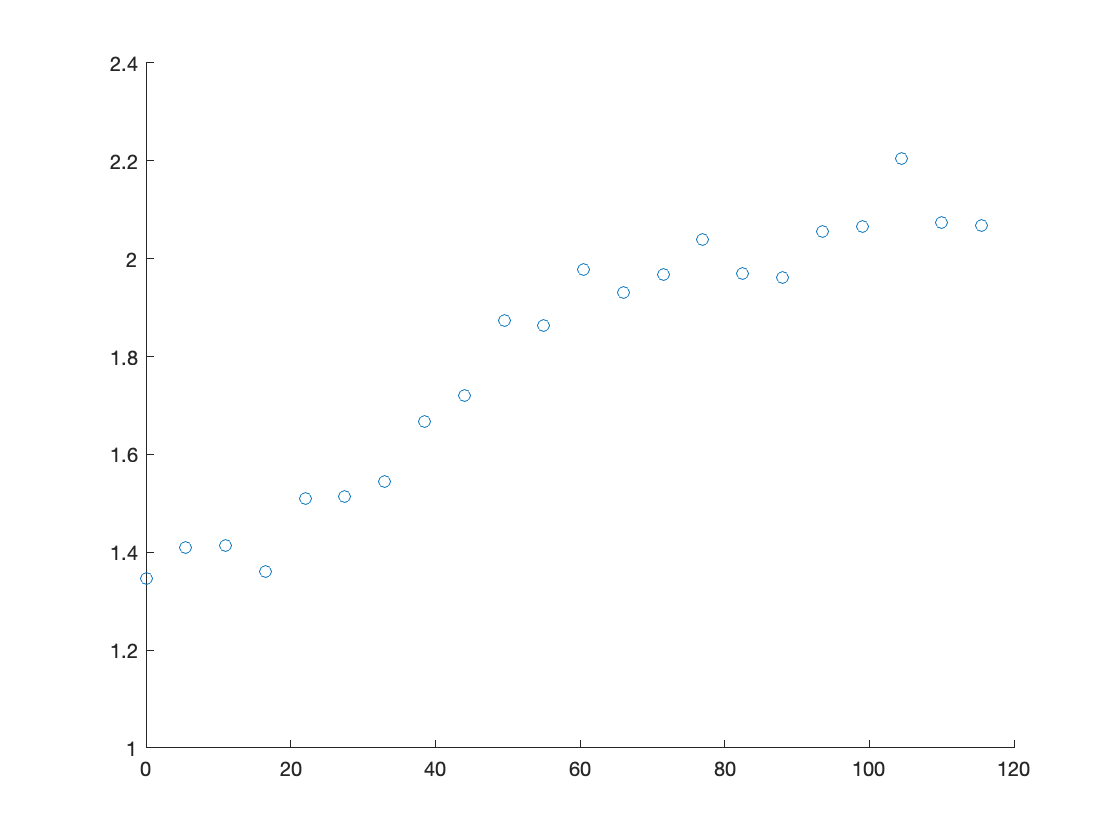

directory = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/results_from_time_0/location.dat";
[location] = RadiusOfOrganoid(directory);

displacement = importfile_displacement(directory);
time = double(importfile_time(directory));

LuminalPositions = zeros(height(displacement), width(displacement)); % creates new table filled with zero the size of location data file
MyoepithelialPositions = zeros(height(displacement), width(displacement)); % creates new table filled with zero the size of location data file

for i = 1:height(displacement)
    
    for j = 1:width(displacement)-5
        
        if displacement(i,j) == "Luminal"
            LuminalPositions(i,j) = str2double(displacement(i,j));
            LuminalPositions(i,j+1) = str2double(displacement(i,j+1));
            LuminalPositions(i,j+2) = str2double(displacement(i,j+2));
            LuminalPositions(i,j+3) = str2double(displacement(i,j+3));
            LuminalPositions(i,j+4) = str2double(displacement(i,j+4));
            LuminalPositions(i,j+5) = str2double(displacement(i,j+5));
        
        elseif displacement(i,j) == "Myoepithelial"
            
            MyoepithelialPositions(i,j) = str2double(displacement(i,j));
            MyoepithelialPositions(i,j+1) = str2double(displacement(i,j+1));
            MyoepithelialPositions(i,j+2) = str2double(displacement(i,j+2));
            MyoepithelialPositions(i,j+3) = str2double(displacement(i,j+3));
            MyoepithelialPositions(i,j+4) = str2double(displacement(i,j+4));
            MyoepithelialPositions(i,j+5) = str2double(displacement(i,j+5));
        
        end
    
    end

end

LuminalPositions = LuminalPositions(:,any(LuminalPositions)); % removes collumns containing only zeros
MyoepithelialPositions = MyoepithelialPositions(:,any(MyoepithelialPositions)); % removes collumns containing only zeros


for row = 1:height (LuminalPositions)
    for counter = 1:(width(LuminalPositions)-1)/4
        j = (counter * 4)-2;
        r(row,counter) = sqrt(LuminalPositions(row,j)^2 + LuminalPositions(row,j+1)^2 + LuminalPositions(row,j+2)^2);
    end
end

for row = 1:height (MyoepithelialPositions)
    for counter = 1:(width(MyoepithelialPositions)-1)/4
        j = (counter * 4)-2;
        r2(row,counter) = sqrt(MyoepithelialPositions(row,j)^2 + MyoepithelialPositions(row,j+1)^2 + MyoepithelialPositions(row,j+2)^2);
    end
end

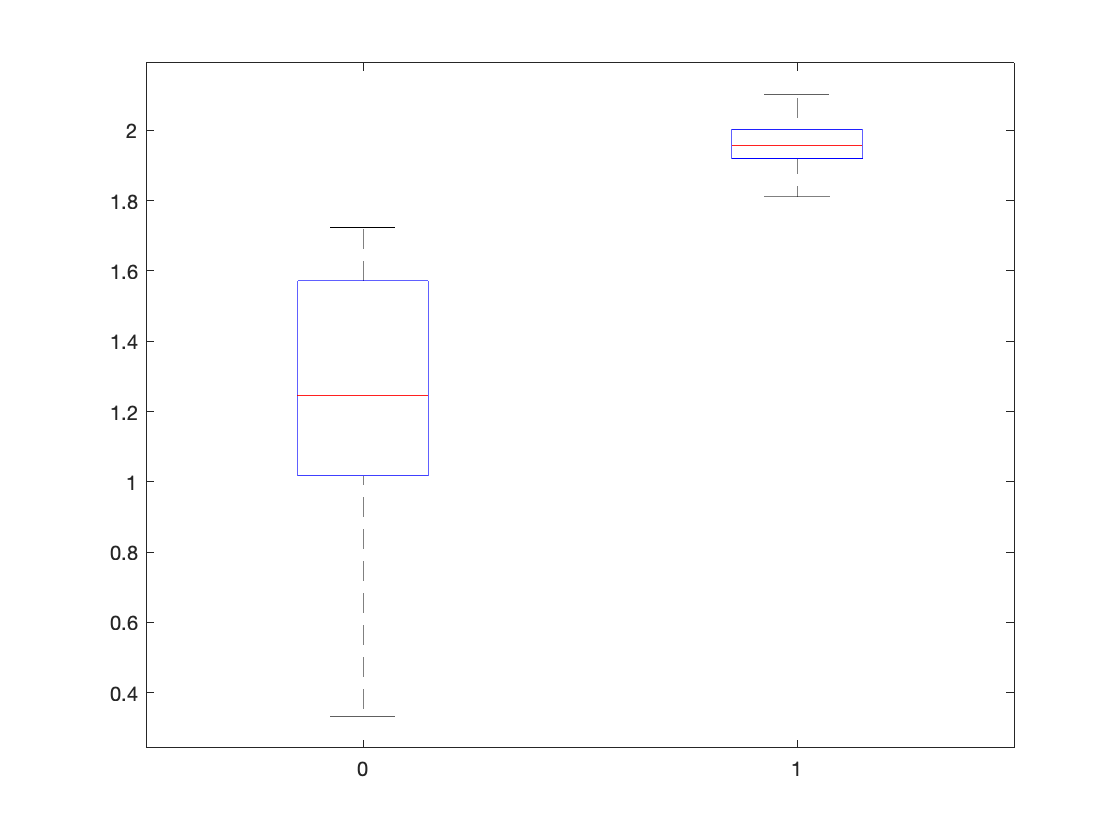

x = r(end,:);
y = r2(end,:);
g = [x y];
C = [zeros(1,length(x)) ones(1,length(y))];

boxplot(g,C)